# Stages: --> specifications

### **Encoding **

#### 1 - Reading the image --> Matrix 256x256

####  2- Divide it into block 8X8

####  3- pass each block to the quantization stages:

-     Normalization 

-     multiply by quantization table to collect the high-frequency

-     zigzag ordering to be able to compress zeros

-     run length encoding for each block

#### 4- collect the run length codes of each block in one array

#### 5- lossless compression using hufman

### **Decoding**

#### 1- pass the hufman code and its dectionary of the whole image to decoder

#### 2- decode hufman and get the run length coe

#### 3- return run length to its original form with all zeros

#### 4- zigzag inverse reordering for each block and by deviding the code 64 pixels

#### 5-show the decoded Image

The quality of the images depend on the quantization ratio and the lossless encoding algrithms --> may arithmatic give more compression ratio.

the compression ratio is clarified after showing the decoded images

Q1 does not neglect any values but the most frequencies are decreased to a factor of 16

Q2 neglect any frequencies below the half of 256 at the end

# DCT

% clear
% clc; close all
function [decoded,bitsBefore,bitsAfter] = JPEG(Image,Q_table)
    [code1,Table,Q1] = JPEG_E(Image,Q_table);
    [row, column] = size(Image);
    [decoded,bitsBefore,bitsAfter] = JPEG_Decode(code1,Table,Q1,row,column);
end

%------------------------------------------------
%Dividing the image into 8*8 blocks

function [code1,Table,Q1] = JPEG_E(Image,Quantization)
    [r,c] = size(Image);
    
    rows = 8*ones(1,r/8);
    columns = 8*ones(1,c/8);
    
    ImBlocks = mat2cell(double(Image),rows,columns);
    [rowB,columnB]= size(ImBlocks);
    
    newImageO1 = zeros(r,c);
    newImageO2 = zeros(r,c);
    
    
    RLs1 = [];
    RLs2 = [];

# Using Quantization table 1

    %------------------------------------------------
    RL1 = [];
    for i = 1: rowB
        for j = 1:columnB
            [RL1,Q1] = Encoding(ImBlocks{i,j},Quantization);
            RLs1 = [RLs1, RL1];
        end
    end

## Calculating Probabilities

    % Count occurences of each symbol using hist function in matlab
    [freq, elements] = hist(RLs1,unique(RLs1));
    % Normalize probabilities
    freq=freq/sum(freq);

## Huffman Encoding

    % Generate Huffman Code Table for symbols
    symbols=string(elements); % As my huffman code generator works on string symbols
    Table = Huffman(freq,symbols);
    
    % Encode the array of symbols using the Huffman_encoder by the table
    sequence = string(RLs1);
    code1 = Huffman_encoder(sequence,Table);
end

## Decoding Stage

### Huffman Decoding

function [newImageO2,bitsBefore,bitsAfter] = JPEG_Decode(code1,Table,Q1,row,column)
    RecievedCode = Huffman_decoder(code1,Table);
    RecievedCode;

    newImageO2 = decoding(RecievedCode,Q1,row,column);

    bitsBefore = row*column*8;
    bitsAfter = length(convertStringsToChars(code1));
    compression1 = bitsBefore / bitsAfter;
end

The compression in the first quantization is less but the picture is higher quality than the second which is high compression lower qyality.

Quantization table one is chosen for :

1- low compression ratio

2- not neglecting all high frequencies but get a lower ratio of them

Quantization table 2 is chosen for :

1- higher compression ratio

2-  neglecting all high frequencies less than half 256

### The sizes is clearly different after saving them to the pc with its compression 

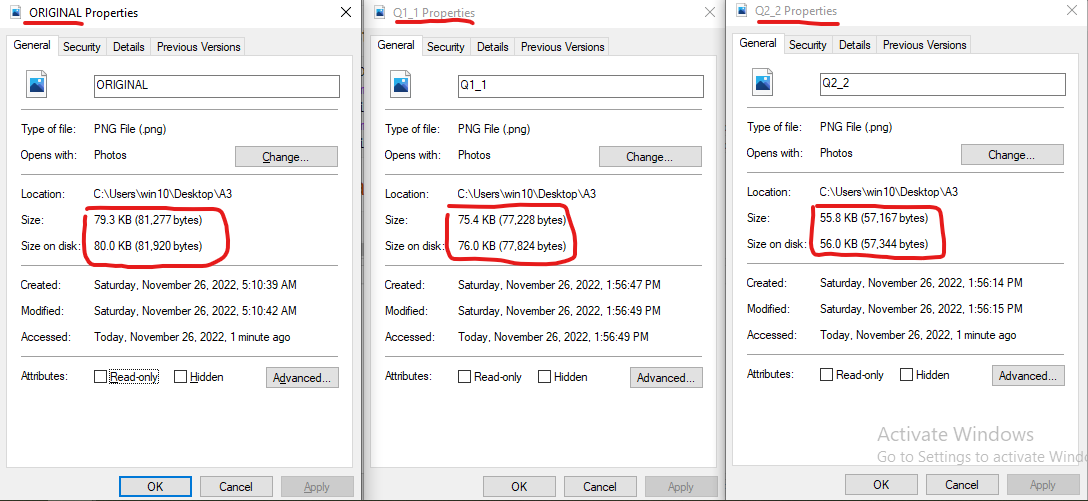

# Collection of the encoding Phase

Input : the block of the image 8x8 , the quantization table number

output: the runlength code & the quantization table to be used in decofing

function [RL,Q] = Encoding(block , n)  
    base = zeros(8,8);
    out = zeros(8,8);
    %%%%%%%%%%%%%%%%%%%Normalization Stage%%%%%%%%%%%%%%%
    for u = 0:7
        for v = 0:7
            for x = 0:7
                for y = 0:7
                    base(x+1,y+1) = (1/16) * cos(u * (pi/16) * (2*x +1)) * cos(v * (pi/16) * (2*y +1));
                end
            end
            out(u+1,v+1) = sum(sum(block.*base));
    
        end
    
    end
    
    out(1,:) = out(1,:) / 2;
    out(:,1) = out(:,1) / 2;

## Quantization

    Q = QuantizationTable(n);
    Qout = out./Q;
    Qout = round(Qout);


## Zigzag

    Q1D = zigzagOrder(Qout);

## Run Length encoding

    RL = runLength(Q1D);
    return
end

# Collection of the decoding Phase

Input: hufman code for whole picture 256x256 , dictionary (table to search about codes) and quantization table

Output: the new Image decoded 

function newImage = decoding(RecievedCode,Q,row,column)

## Runlength decoder

    DecodedRL = runLengthDecoder(RecievedCode);

## Preparation for new Image Reconstruction

    rows = 8*ones(1,row/8);
    columns = 8*ones(1,column/8);
    newImage = zeros(row,column);
    newImBlocks = mat2cell(double(newImage),rows,columns);
    [rowB,columnB]= size(newImBlocks);

for loop starting

    n=0;
    for i = 0 : rowB - 1
        for j = 0 : columnB - 1

## Inverse Zigzag

       InverseZig = zigzagInverse(DecodedRL(1+n*64:64+n*64));
       n=n+1;

## Dequantizing

        DeQuantized = InverseZig.*Q;

## IDCT

        [R,C]=size(DeQuantized);
        %Intializations
        basis=zeros(R,C);
        if R~=8 || C~=8
            disp('Error in block size');
        end
        %looping over the size of the basis and size of the input
        idct_result=zeros(8,8);
        for u=0:7
            for v=0:7
                for x=0:7
                    for y=0:7
                        %constructing the basis block
                        basis(x+1,y+1)=  (cos((1/16)*(2*x+1)*u*pi))*(cos((1/16)*(2*y+1)*v*pi));
                    end
                end
                % multiplying each value of encoded_block to the corresponding
                % basis block and summing the result and storing it in the result_Idct block
                idct_result=idct_result+DeQuantized(u+1,v+1)*basis;
            end
        end
        
        idct_result = round(idct_result);
        %%put each block in its place in the new image
        newImage(i*8+1:i*8+8,j*8+1:j*8+8) = idct_result;


for loop ending

        end
    end
    
    return
end



## Function Used

### Quantization Tables

Input: integr 1 or 2  for the quantization table choice

output: Quantization table

function Table = QuantizationTable(x)
    if (x == 1)  % for Low compression
        Table = [1 1 1 1 1 2 2 4
            1 1 1 1 1 2 2 4
            1 1 1 1 2 2 2 4
            1 1 1 1 2 2 4 8
            1 1 2 2 2 2 4 8
            2 2 2 2 2 4 8 8
            2 2 2 4 4 8 8 16
            4 4 4 4 8 8 16 16];
    elseif (x == 2)  % for high compression
        Table =[1 2 4 8 16 32 64 128;
            2 4 4 8 16 32 64 128;
            4 4 8 16 32 64 128 128;
            8 8 16 32 64 128 128 256;
            16 16 32 64 128 128 256 256;
            32 32 64 128 128 256 256 256;
            64 64 128 128 256 256 256 256;
            128 128 128 256 256 256 256 256];
    else
        disp('Error in choose X');
    end
    return 
end



### Zigzag ordering

Input: 2D matrix 

Output: 1D array ordered zigzaging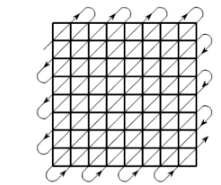

function Q1D = zigzagOrder(Qout)
    [r, c] = size(Qout); % 8 * 8
    direction = 1;
    counter = 1;
    Q1D = zeros(1,r*c);
    i = 1;
    j=1;
    while counter < r*c
        if(direction == 1)
           while 1
                Q1D(1,counter) = Qout(i,j);
                if counter >= r * c
                    break;
                end
                    counter = counter + 1;
                %%Stop at the borgers to reverse directions    
                if (j == c) || (i == 1)  
                    direction = 0;
                    if j == c
                        i = i-1;
                    else
                        j = j+1;
                    end
                    
                    break;
                else
                    i = i-1;
                    j = j+1;
                end
           end
            
        else
            while 1
                Q1D(1,counter) = Qout(i,j);
                if counter >= r * c
                    break;
                end
                counter = counter + 1;
                %% Stop at the borders to reverse direction
                if (i == c) || (j == 1)
                    direction = 1;
                    if i == c
                        j = j + 1;
                    else
                        i = i+1;
                    end
                    break;
                else
                    i = i+1;
                    j = j-1;
                end
           end
        end
    
    end
return
end

### Zigzag Inverse

Input: 1D ordered array

Output: 2D array zizaged filling

function Q2D = zigzagInverse(Q1D)
    Q2D = zeros(sqrt(length(Q1D)));
    [r, c] = size(Q2D); % 8 * 8
    direction = 1;
    counter = 1;
    
    i = 1;
    j=1;
    while counter < r*c
        if(direction == 1)
           while 1
                Q2D(i,j) = Q1D(1,counter);
                if counter >= r * c
                    break;
                end
                    counter = counter + 1;
                %% stop at the borders to reverse directions    
                if (j == c) || (i == 1)
                    direction = 0;
                    if j == c
                        i = i-1;
                    else
                        j = j+1;
                    end
                    
                    break;
                else
                    i = i-1;
                    j = j+1;
                end
           end
            
        else
            while 1
                Q2D(i,j) = Q1D(1,counter);
                if counter >= r * c
                    break;
                end
                counter = counter + 1;
                %% stop at the borders to reverse directions
                if (i == c) || (j == 1)
                    direction = 1;
                    if i == c
                        j = j + 1;
                    else
                        i = i+1;
                    end
                    break;
                else
                    i = i+1;
                    j = j-1;
                end
           end
        end
    
    end
    return
end

### RunLength Encoder

ex : 0 0 0 1 --> 0 3 1    ||   58 0 0 0 0 48 -->  58 0 4 48

Input: 1D array of large number of zeros

Output: 1D array with less number o zeros

function RL = runLength(x)
    code = [];
    n = 0;
    for i = 1:length(x)
        if (x(i) == 0)
            n = n + 1;
            continue;
        else
            if(n>0)
               code = [code,0,n];
            end
            n = 0;
            code = [code,x(i)];
        end
    end
    if(x(length(x) )== 0)
        code = [code,0,n];
    end
    RL = code;
    return
end


### RunLength Decoder

ex: 0 5 48 --> 0 0 0 0 0 48

Input: 1D less zeros array

Output: 1D with original number of zeros

function DecodedRL = runLengthDecoder(code)
    decoded = [];
    prvZero = 0;
    for i = 1:length(code)
        if(code(i) ~= 0 && prvZero == 0)
            decoded = [decoded,code(i)];
        elseif(code(i) == 0 && prvZero == 0)
            prvZero = 1;
            continue;
        else
            prvZero = 0;
            for j = 1: code(i)
                 decoded = [decoded,0];
            end
        end    
    end
    DecodedRL = decoded;
    return
end


# **Airthimatic Encoder**

## **Constructing array of structs with symbols bounds, probabilities, and characters**

function arr = arith_table(symbols,prob)
    c = struct();
    c.symbol = 'c';
    c.prob = 0.0000;
    c.lower = 0.0000;
    c.upper = 0.0000;
    
    arr = repmat(c,1,length(symbols));
    %arr is the first representation of the symbole depending on their
    %probabilities
    for i = 1:length(symbols)
        arr(i).symbol = symbols(i);
        arr(i).prob = prob(i);
        if i == 1
            arr(i).lower = 0.0000;
            arr(i).upper = prob(i);
    
        elseif i == length(symbols)
            arr(i).lower = arr(i-1).upper;
            arr(i).upper = 1.0000;
    
        else
            arr(i).lower = arr(i-1).upper;
            arr(i).upper = arr(i-1).upper + prob(i);
        end
    end
end

## Determining the lower and higher bounds of the input sequence

function [L,H]= Find_Range(word,symbols,props)
% Check the sum of propbabilities is equal 1
if sum(props)==1
%initialize the ranges line
line = zeros(1,length(props)+1);
number_of_points = length(line);
line(1) = 0;
line(2:number_of_points) = props;
for i=2:number_of_points
   line(i) = line(i-1)+line(i); 
end
line1 = line;
for i=1:length(word)
    % get the index of the letter
    current_symbol = find(symbols==word(i));
    new_range_start = vpa(line(current_symbol));
    new_range_end = vpa(line(current_symbol+1));
    new_range_diff = vpa(new_range_end-new_range_start,5);
    line = line1*new_range_diff+new_range_start*ones(1,number_of_points);
    
end
L = line(1);
H = line(number_of_points);
end
end
function [L,H] = get_L_H(input,arr2,symbols)
    arr = arr2;
    for i = 1: length(input)
        for j = 1:length(arr)
            if(input(i) == arr(j).symbol)
                arr2(1).lower = arr2(j).lower;
                arr2(length(arr)).upper = arr2(j).upper;
                for k = 1:length(arr)
                    arr2(k).prob = arr2(k).prob * arr(j).prob;
                end
                for k = 1:length(arr2)
                    if k == 1
                        arr2(k).upper = arr2(k).lower + arr2(k).prob ;
                    elseif k == length(symbols)
                        arr2(k).lower = arr2(k-1).upper;
                    else
                        arr2(k).lower = arr2(k-1).upper;
                        arr2(k).upper = arr2(k-1).upper + arr2(k).prob;
                    end
                end
                break;
            end
        end
    end
    L = arr2(1).lower;
    H = arr2(length(arr)).upper;
end

## Getting the binary code to fit between L and H

function code = get_code(L,H)
    b = struct();    
    b.binary = 0.0000;
    b.upper = 0.5000;
    b.lower = 0.0000;
    block = [b b];
    
    block(2).binary = 1.0000;
    block(2).lower = 0.5000;
    block(2).upper = 1.0000;
    
    
    found = 0.0000;
    
    while(found == 0.0000)
    
        if ((L<= block(1).lower) & (H>block(1).upper))
            found = 1.0000;
            code = block(1).binary;
        elseif ( (L<= block(2).lower) & (H>block(2).upper) )
            found = 1.0000;
            code = block(2).binary;
        else
            temp = 0.0000;
            if (L > block(1).lower) & (H < block(1).upper)
                block(2).binary = [block(1).binary 1.0];
                block(1).binary = [block(1).binary 0.0];
                block(2).upper = block(1).upper;
                for i = 1:length(block(2).binary)
                    temp = temp + 2^-i * (block(2).binary(i));
                end
            else
                block(1).binary = [block(2).binary 0.0];
                block(2).binary = [block(2).binary 1.0];
                block(1).lower = block(2).lower;
                for i = 1:length(block(2).binary)
                    temp = temp + 2^-i * block(2).binary(i);
                end
            end
            block(2).lower = temp;
            block(1).upper = temp;
        end
    end
end

function code = arith_encode(symbols,arr2,input)
    [L,H] = get_L_H(input,arr2,symbols);
    code = get_code(L,H);
end

# **Airthimatic Decoder**

function sequence = arith_decode(code,Length,arr,symbols)
    seqlen = Length;
    sequence = [];
    deciCode = 0;
    %binary to decimal
    for i = 1:length(code)
        deciCode = deciCode + 2^-i * (code(i));
    end
    arr3 = arr;
    while(seqlen > 0)
        for i = 1:length(arr)
            if(arr3(i).lower < deciCode) & (arr3(i).upper > deciCode)
                sequence = [sequence arr(i).symbol];
                break;
            end
        end
        arr3(1).lower = arr3(i).lower;
        arr3(length(arr)).upper = arr3(i).upper;
        for k = 1:length(arr)
            arr3(k).prob = arr3(k).prob * arr(i).prob;
        end
        for k = 1:length(arr)
            if k == 1
                arr3(k).upper = arr3(k).lower + arr3(k).prob ;
            elseif k == length(symbols)
                arr3(k).lower = arr3(k-1).upper;
            else
                arr3(k).lower = arr3(k-1).upper;
                arr3(k).upper = arr3(k-1).upper + arr3(k).prob;
            end
        end
        seqlen = seqlen -1;
    end
end



# Huffman 


% FUNCTION takes two arrays(row arrays) and 
% returns a table containing all the symbols
% with their corresponding codes
function T= Huffman(probabilty,symbol)

    if abs(sum(probabilty)-1)>0.01
        disp("Error! Please revise the probabilites as their sum is != 1");
        T=nan;
        return;
    elseif length(probabilty)~=length(symbol)
        disp("# of symbols != # of probabilities")
    end
    
    %% preparing fields to create array of structs
    
    % Making copy of original inputs
    input_symbols=symbol; input_freq=probabilty;
    
    % sorting probabilites descendingly 
    % (with their symbols to avoid misorder between each symbol and its probability)
    temp=array2table([probabilty' symbol'], "VariableNames",["probabilty","symbol"]);
    temp=sortrows(temp,'probabilty','descend');
    probabilty=double(temp.probabilty');
    symbol=temp.symbol';
    
    % initializing empty array of strings to carry code of each symbol
    for i=length(probabilty):-1:1
        c(i)=string();
    end
    
    % creating array of structs for symbols and data
    for i=length(probabilty):-1:1
        array(i)=struct('prob',probabilty(i),'symbol',symbol(i),'code',c(i));
    end
    
    
    %% FUNCTION takes array of structs and return one struct carrying symbols and codes
    FinalStruct=recursive_Huffman(array);
    
    
    % Extract the symbols and codes as 2 arrays from the FINAL struct
    Symbol=FinalStruct.symbol;
    Code=reverse(FinalStruct.code); %reverse as the huffman code is read from 
                                    %right of the diagram (arrows) to the left
    
    
    % tabulate the symbols and codes and sort the rows based on symbol letters
    T=table(Symbol,Code);
    T=sortrows(T,'Symbol');
    
    %% Adding length and probability of each code to the table
    % sort the probabilities based on the alphabet since the output 
    % of the function is sorted on alphabet but doesn't have probabilites
    temp=array2table([input_freq' input_symbols'], "VariableNames",["input_freq","input_symbols"]);
    temp=sortrows(temp,'input_symbols','ascend');
    Frequency=double(temp.input_freq);
    % Calculating length of each code
    Length=strlength(table2array(T(:,"Code"))); 
    
    % add to table
    T.Length=Length;
    T.Frequency=Frequency;
    
    %% Print Table and statistics about it
    %T % displaying the table
    %
    %entropy=-sum(Frequency(:).*log2(Frequency(:))); 
    %averageLength=sum(Frequency(:).*Length(:));
    %efficiency=entropy/averageLength*100; 
    %
    %fprintf("Entropy=%6.4f -- Average Length=%6.4f -- Efficiency=%6.4f%%\n",entropy,averageLength,efficiency);
    %
end

% Function encodes an array of symbols (file) based on table of codes
function s = Huffman_encoder(f,T)
    s="";
    for i=1:length(f)
        s=s+T.Code(T.Symbol==f(i));
    end
end

% Function decodes an array of symbols (file) based on table of codes
function output = Huffman_decoder(input,T)
    %convert the single string (bit sequence) to array of characters
    input=input.char();
    codeWord="";
    output=[]; c=0;
    for i=1:length(input)
        codeWord=codeWord+input(i); % append the bits to form a code
        
        if sum(T.Code==codeWord)==1  %% if a code is formed then decode it to a symbol
            c=c+1;
            output(c)=str2double(T.Symbol(T.Code==codeWord)) ;
            codeWord="";
        end
    end

end
%% FUNCTION takes array of structs and return one struct carrying symbols and codes
function x=recursive_Huffman(x)

    if length(x)==1 %input is 1 symbol
        x.code="0";
        return;
    elseif length(x)==2 %Stop condition for recursion & handle if user input is only 2 symbols
        x(1).code=x(1).code+"0";
        x(2).code=x(2).code+"1";
        
        %Combining
        newprob=x(1).prob+x(2).prob;
        newsymbol=[x(1).symbol;x(2).symbol];
        newcode=[x(1).code;x(2).code];
        x=struct('prob',newprob,'symbol',newsymbol,'code',newcode);
    
        return;
    else %general case of n inputs
    
        %take last 2
        last2=x(end-1:end);
        x=x(1:end-2);
    
        %give 0 & 1
        last2(1).code=last2(1).code+"0";
        last2(2).code=last2(2).code+"1";
    
        %Combining
        newprob=last2(1).prob+last2(2).prob;
        newsymbol=[last2(1).symbol;last2(2).symbol];
        newcode=[last2(1).code;last2(2).code];
        newStruct=struct('prob',newprob,'symbol',newsymbol,'code',newcode);
    
        %Re-insert to the group
        x=[x newStruct];
    
        %Sort based upon new probabilities using tables of MATLAB
        t=struct2table(x);
        sorted=sortrows(t,'prob','descend');
        x=table2struct(sorted)';
    
        %Recursive call: send new array of structs containing the newly
        %combined struct having the sum of 2 leastg probabilities
        x=recursive_Huffman(x);
    end
end
